datapath = ...
    {"/Volumes/yaochen/Active/Pingchuan/2020FL/1216AchsensorHPCICI005/",...
    "/Volumes/yaochen/Active/Pingchuan/2021Fall/0910AchsensorHPC001_puffing/",...
    "/Volumes/yaochen/Active/Pingchuan/2021Fall/0910AchsensorHPC003/",...
    "/Volumes/yaochen/Active/Pingchuan/2021Fall/101521AchsensorHPC001/"...
    }

datapath = 1×4 cell array
    {["/Volumes/yaochen/Active/Pingchuan/2020FL/1216AchsensorHPCICI005/"]}    {["/Volumes/yaochen/Active/Pingchuan/2021Fall/0910AchsensorHPC001_puffing/"]}    {["/Volumes/yaochen/Active/Pingchuan/2021Fall/0910AchsensorHPC003/"]}    {["/Volumes/yaochen/Active/Pingchuan/2021Fall/101521AchsensorHPC001/"]}




StateYao_file = ...
    {{"puffing_1/1216AchsensorHPCICI005_Analysis2022-09-24.mat",...
    "puffing_2/1216AchsensorHPCICI005_Analysis2022-09-24.mat",...
    "puffing_3/1216AchsensorHPCICI005_Analysis2022-09-24.mat"},...
    {"puffing_2_analysis_offset0_ROIadjusted_20221215.mat"},...
    {"puffing_3/0910AchsensorHPC003_Analysis2022-09-24.mat"},...
    {"puffing_3_analysis_ROI_adjusted_20221215.mat",...
    "puffing_5_analysis_ROI_adjusted_20221215.mat"}...
    }

StateYao_file = 1×4 cell array
    {1×3 cell}    {1×1 cell}    {1×1 cell}    {1×2 cell}




summary_files = {};
summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Slice_puffing/';




baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation
CyclePositions = 1;

FigureVisible = 'off'

FigureVisible = 'off'

puffing_GrandSummary_lft_reponse_norm = [];
puffing_GrandSummary_intensity_reponse_norm = [];
puffing_acqs = {};
puffing_intensity = {};
puffing_lft = {};
puffing_time = {};

for i = 1:4
    cd(datapath{i})
    for j = 1:length(StateYao_file{i})
        load(StateYao_file{i}{j})
        puffing_acqs{i}{j} = [stateYao.CyclePositions(1) stateYao.CyclePositions(end)];
        
        Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions);
        CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions);
    
        [lft_puffing, intensity_puffing, lft_puffing_response_all, intensity_puffing_response_all, lft_puffing_response_norm_all, intensity_puffing_response_norm_all, AcqTime] = Puffing(baseline_acq_num, epoch_acq_num, j, FigureVisible);
%         save([stateYao.baseName,'puffing',num2str(j),'.mat'],'lft_puffing', 'intensity_puffing', 'lft_puffing_response_all', 'intensity_puffing_response_all', 'lft_puffing_response_norm_all', 'intensity_puffing_response_norm_all', 'AcqTime');
        currTime = datestr(datetime('now'));
        currTime = currTime(1:11);
        summary_files{i}{j} = [stateYao.baseName, '_', currTime, '_', num2str(j), '.mat'];

        copyfile([convertStringsToChars(datapath{i}), stateYao.baseName, '_', currTime,'_', num2str(j), '.mat'], summary_path);

        puffing_intensity{i}{j} = intensity_puffing;
        puffing_lft{i}{j} = lft_puffing;
        puffing_time{i}{j} = AcqTime;
        
        puffing_GrandSummary_lft_reponse_norm = [puffing_GrandSummary_lft_reponse_norm;[NaN NaN];lft_puffing_response_norm_all];
        puffing_GrandSummary_intensity_reponse_norm = [puffing_GrandSummary_intensity_reponse_norm; [NaN NaN]; intensity_puffing_response_norm_all];
    end
    

end

Cycle position 1, cell 1 in image 22, mask is empty.



cd(summary_path)
save('puffing_summaries.mat', 'summary_files', 'puffing_acqs', 'puffing_intensity', 'puffing_lft', 'puffing_time', 'puffing_GrandSummary_lft_reponse_norm', 'puffing_GrandSummary_intensity_reponse_norm')

cd(summary_path)
load('puffing_summaries.mat')

k = 1;
for i = 1:4
    
    for j = 1:length(puffing_lft{i})
        figure('visible', FigureVisible)
        subplot(2,1,1)
        plot(puffing_time{i}{j}*60, puffing_lft{i}{j})
        xlabel('Time (s)')
        ylabel('Lifetime (ns)')

        subplot(2,1,2)
        plot(puffing_time{i}{j}*60, puffing_intensity{i}{j})
        xlabel('Time (s)')
        ylabel('Intensity')

        saveas(gcf, ['puffing_', num2str(k), '.png'])
        k = k+1;


    end
end

n_Cell = size(stateYao.mask.ROI{1}, 2);
Acq_length = length(stateYao.CyclePositions);

lft_puffing = NaN(Acq_length,n_Cell);
intensity_puffing = NaN(Acq_length,n_Cell);

for i_Acq = 1:Acq_length
    for j_Cell = 1:n_Cell
        lft_puffing(i_Acq,j_Cell) = stateYao.Results.spc_calculateROIvals.LifetimeMap{1}{i_Acq}(j_Cell);
        intensity_puffing(i_Acq,j_Cell) = stateYao.Results.spc_calculateROIvals.Projection{1}{i_Acq}(j_Cell);
    end
end

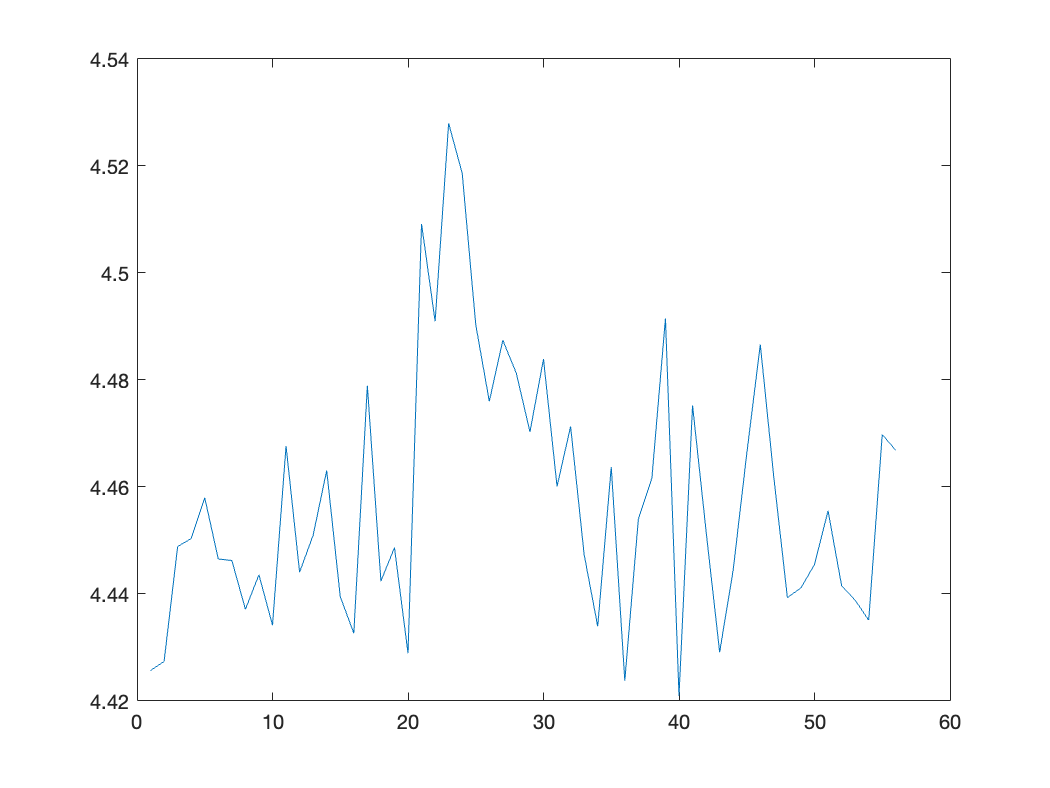

figure
plot(lft_puffing)

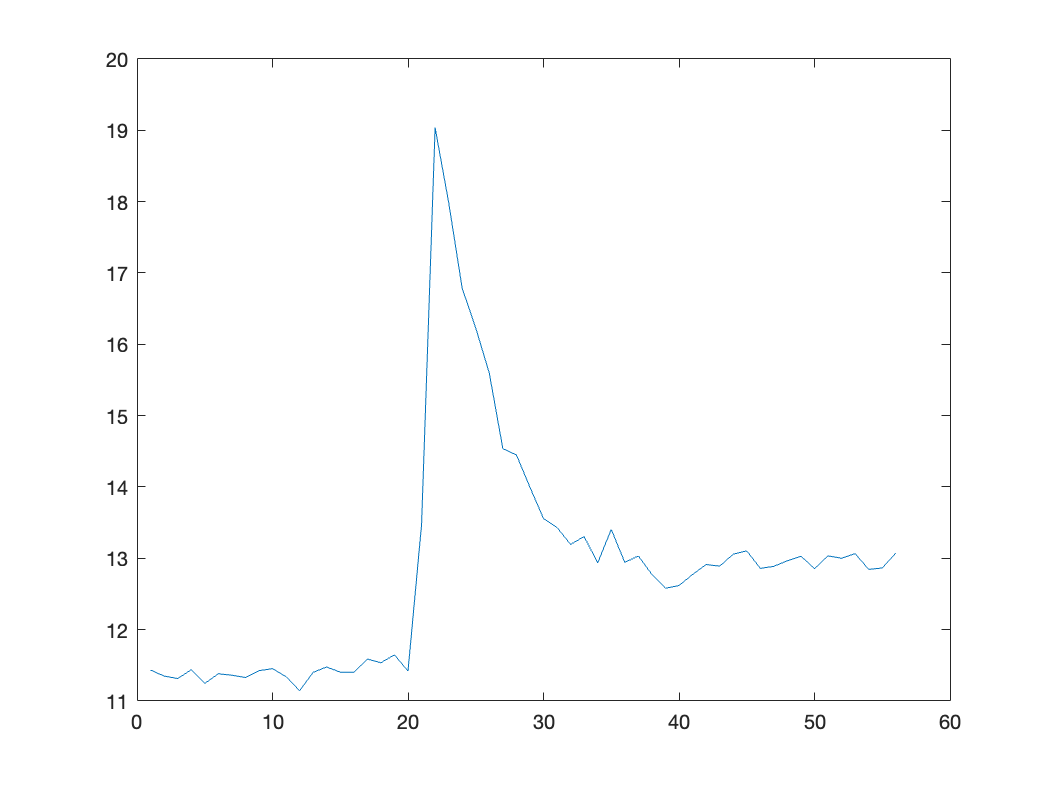


figure
plot(intensity_puffing)